cd(fileparts(matlab.desktop.editor.getActiveFilename));

tbl = readtable("dati/tcurve.txt", NumHeaderLines=3);
tbl.Properties.VariableNames = ["freq", "abs", "phase"];

tbldata = readtable("dati/AD8031_Gain1e3.txt", NumHeaderLines=3);
tbldata.Properties.VariableNames = ["freq", "abs", "s_abs","phase","s_phase"];

% converto in modulo lineare
tbl.abs = 10.^(tbl.abs/20);
% tbldata.s_abs = 3.8e-4 * ones([size(tbldata.s_abs), 1])

% valori iniziali componenti
R1 = 99.9e3;
C1 = 100e-9;
R2 = 994;
C2 = 47e-9;

t1 = R1*C1;
t2 = R2*C2;

% p(1)=tau1, p(2)=tau2, p(3)=R1, p(4)=C2
% guess iniziale
p0 = [t1, t2, R1, C2];


H = @(p,f) (1j*2*pi*f.*p(1)) ./ ...
           ( (1 + 1j*2*pi*f.*p(1)) .* (1 + 1j*2*pi*f.*p(2)) + 1j*2*pi*f.*p(3).*p(4) );
H_ab = @(p,f) (1j*2*pi*f*p(1)) ./ ( (1 + 1j*2*pi*f/p(2)) .* (1 + 1j*2*pi*f/p(3)));


G = @(p,f) abs(H(p,f))

G = function_handle with value:
    @(p,f)abs(H(p,f))


G_ab = @(p, f) abs(H_ab(p, f))

G_ab = function_handle with value:
    @(p,f)abs(H_ab(p,f))


A = @(p,f) angle(H(p,f))

A = function_handle with value:
    @(p,f)angle(H(p,f))



covabs=1./tbldata.s_abs.^2;
covphase=1./tbldata.s_phase.^2;

% fit non lineare
[popt,R,J,ccovm, MSE]= nlinfit(tbldata.freq,tbldata.abs,G,p0,"Weights",covabs);

[abpopt,abR,abJ,abccovm, abMSE]= nlinfit(tbldata.freq,tbldata.abs,G_ab,[t1, 68, 31.4e3, 0],"Weights",covabs);



[poptph,Rph,Jph,ccovmph, MSEph]= nlinfit(tbldata.freq,tbldata.phase,A,p0,"Weights",covphase);

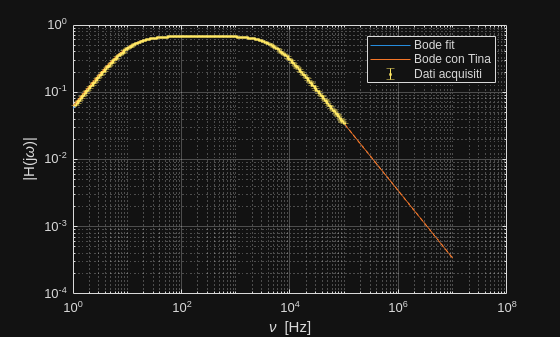


% frequenze logaritmiche da 1 Hz a 1e6 Hz
x = logspace(0, 6, 10000);

% valutazione della funzione con parametri ottimizzati
y = H( popt,x);

% modulo
figure
loglog(x, abs(y))
hold on
loglog(tbl.freq, tbl.abs)
errorbar(tbldata.freq, tbldata.abs,tbldata.s_abs,".")
hold off
legend("Bode fit", "Bode con Tina","Dati acquisiti");
xlabel('\nu [Hz]')
ylabel('|H(j\omega)|')
grid on

exportgraphics(gcf,"grafici/Misura_CRRC.pdf",ContentType="vector");

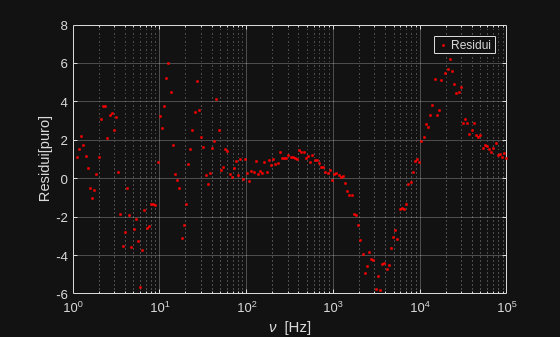



figure
semilogx(tbldata.freq,R,'.r')
legend("Residui");
xlabel('\nu [Hz]')
ylabel('Residui[puro]')
grid on

exportgraphics(gcf,"grafici/Misura_CRRC_residui.pdf",ContentType="vector");

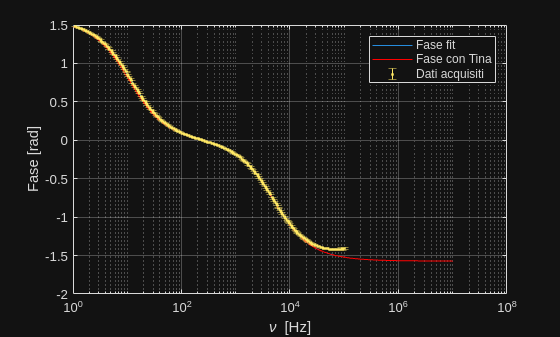


% fase
figure
semilogx(x, angle(y))
hold on
plot(tbl.freq, tbl.phase*pi/180,"r")
errorbar(tbldata.freq, tbldata.phase,tbldata.s_phase,".")
hold off
xlabel('\nu [Hz]')
ylabel('Fase [rad]')
legend("Fase fit", "Fase con Tina","Dati acquisiti")
grid on


fprintf("popt = %.16f\n",popt);

popt = 0.0091490568510090
popt = 0.0000467819497037
popt = 96198.4721137165324762
popt = 0.0000000451003797


fprintf("covm = %.16f\n",sqrt(diag(ccovm/MSE)));

covm = 0.0000004430620204
covm = 0.0000000043826403
covm = 0.0000000000000000
covm = 0.0000000000036525



fprintf("poptph = %.16f\n",poptph);

poptph = 0.0094232016485877
poptph = 0.0000450858505090
poptph = 92597.6353102350403788
poptph = 0.0000000437444416


fprintf("covmph = %.16f\n",sqrt(diag(ccovmph/MSEph)));

covmph = 0.0000000000171923
covmph = 0.0000000035876759
covmph = 0.0000000000000000
covmph = 0.0000000000055830



fprintf("abpopt = %.16f\n", abpopt);

abpopt = 0.0091490324546526
abpopt = 74.0593530254504060
abpopt = 31547.4602157290137256
abpopt = 0.0000000000000000


fprintf("abcovmph = %.16f\n", sqrt(diag(abccovm/abMSE)));

abcovmph = 0.0000004427671534
abcovmph = 0.0040190932570006
abcovmph = 3.1766558304892714
abcovmph = 0.0000000000000000


fprintf("Chi2 = %f", abMSE);

Chi2 = 6.867805

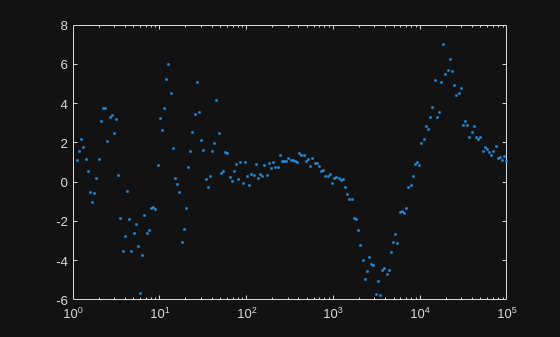


semilogx(tbldata.freq, (abR), '.')